# Rete di Elman

Un notevole risultato sullo stesso dataset da noi analizzato è stato raggiunto da alcuni studenti della facoltà di Ingegneria Informatica del Karpagam Institute of Technology, Coimbatore, India (*all'interno del Paper **Nonlinear Predictive Model of Chemical Process System Using an ELMAN Neural Network** (fonte: IJESC* ) . Tale risultato è stato ottenuto tramite una rete neurale di Elman con:

- 2 neuroni di input

- 2 hidden layers da 10 neuroni nascosti ciascuno

- un neurone di output

- come algoritmo di training: Bayesian regularization backpropagation (funzione: "t*rainbr*") (COME L'ERRORE SI PROPAGA)

- Activation Function: Tan Sigmoid for input-hidden layer and Linear function for hidden-output layer    (CON QUALE FUNZIONE VIENE MANIPOLATO L'INGRESSO DEL NEURONE)

La rete neurale di Elman, chiamata anche rete a stati ricorrenti, è un  tipo di rete neurale ricorrente (RNN) che è particolarmente adatta per  modellare sequenze di dati temporali. È stata introdotta da Jeffrey  Elman nel 1990.

La struttura della rete neurale di Elman può essere considerata come **variazione di una normale rete feed-forward aggiungendo un feedback hidden-hidden attraverso un nuovo strato, il CONTEXT LAYER.**

È costituita da un livello di input, uno o più livelli nascosti (solitamente con funzioni di attivazione sigmoide) e un livello di output. **La peculiarità principale della rete di Elman è  l'aggiunta di uno o più "livelli di stato" (context layer) che rappresentano la memoria interna della rete**. **Questi livelli di stato sono collegati al livello nascosto attraverso connessioni a feedback,  che consentono alla rete di utilizzare informazioni passate durante l'elaborazione dei dati temporali.**

Può catturare le dipendenze a lungo termine nelle sequenze temporali dei dati e modellare le dinamiche del sistema.

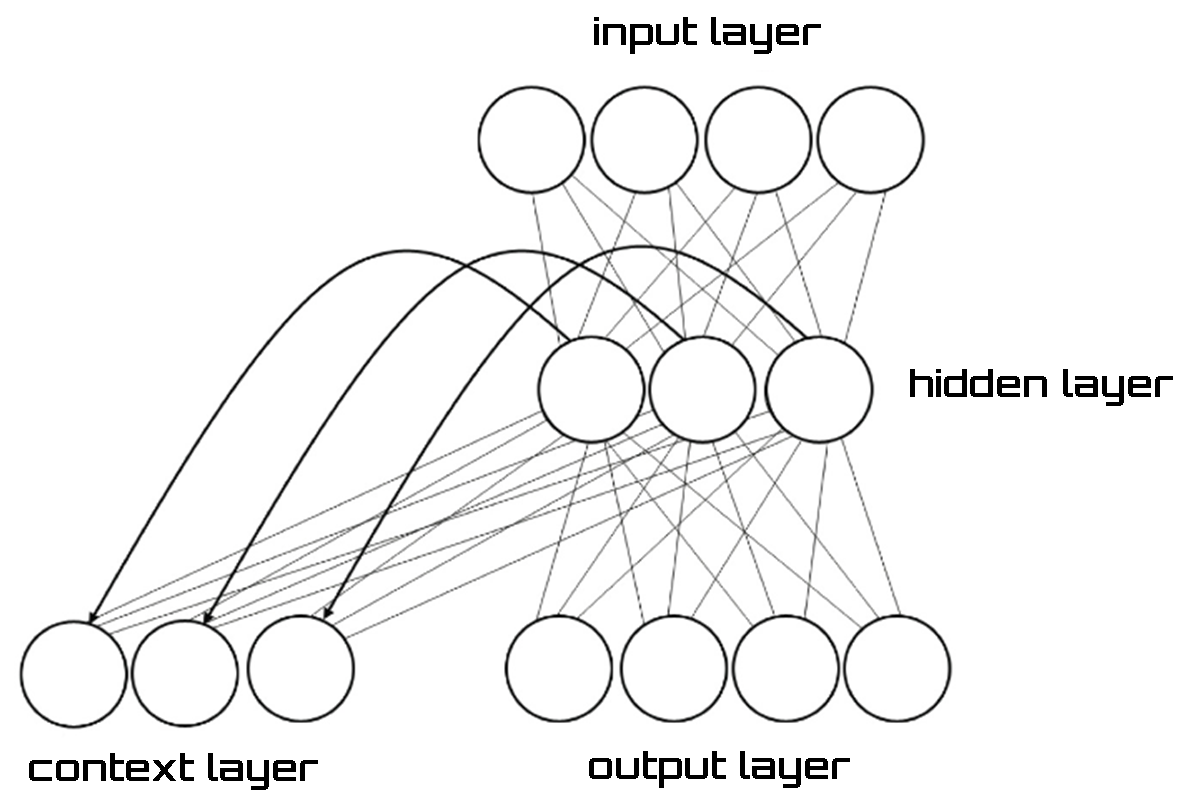

clc
clear all
close all

% Caricamento dei dati
data = load('phdata.dat');
% Estrazione degli ingressi e delle uscite
u1 = data(:, 2);
u2 = data(:, 3);
y = data(:, 4);

% Creazione della matrice
X = [u1 u2];    % colonne
T = y;          % riga

% Normalizzazione dei dati
X = normalize(X);
T = normalize(T);

% Convertire i dati
X = double(X);          % castiamo in double (64 bit = 8 bytes) perché richiesto dalla elman network
T = double(T);

% Definizione dell'architettura della rete neurale Elman
numHiddenUnits = 10;                % numero di neuroni nascosti 


% Create the Elman neural network
%net = newelm(X', T', [numHiddenUnits numHiddenUnits], {}, 'trainbr');                  % vecchio comando

Creazione della rete neurale Elman:

- [numHiddenUnits numHiddenUnits] specifica il numero di neuroni nascosti nella rete. In questo caso, sono specificati 10 neuroni nascosti per ciascun livello nascosto (ho due livelli nascosti);

- {'tansig', 'purelin'} specifica le funzioni di attivazione da utilizzare per i livelli nascosti e di uscita rispettivamente; sono state inserite le parentesi vuote perchè tali funzioni sono di default. La funzione tansig è una Funzione Sigmoide Tangente iperbolica e purelin è una funzione lineare.

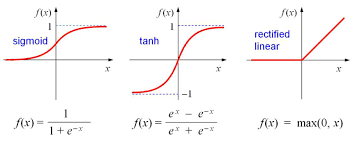

% net = elmannet(1:2, [10 10]);
% net=elmannet(1:2,10,'trainbr');
hiddenLayer1Size = 10;
hiddenLayer2Size = 10;
net = elmannet(1:2,[hiddenLayer1Size hiddenLayer2Size], 'trainbr');  % con 1:2 stiamo indicando che l'uscita dipende da quanto prodotto al passo t-1 e t-2

% Set training algorithm and activation functions
net.trainFcn = 'trainbr';  % Bayesian regularization
net.layers{1}.transferFcn = 'tansig';    % Tan sigmoid for first input-hidden layer
net.layers{2}.transferFcn = 'tansig';    % Tan sigmoid for second input-hidden layer
net.layers{3}.transferFcn = 'purelin';   % Linear function for hidden-output layer
net.numInputs = 2;
net.inputConnect = [1 1;1 1;1 1];
net.inputs{1}.size = 1;
net.inputs{2}.size = 1;
% Prepare training data in the required format
% inputs = con2seq(X');
% targets = con2seq(T');


% Train the Elman neural network
net.trainParam.epochs = 500; 
net.trainParam.showWindow = false;                      % serve per togliere la finestra del Report (ridurre carico CPU)
net = train(net, X', T');
% Use the trained network for prediction
y_sim = sim(net, X')';

noise = 0.001 * randn(length(T), 1);         % Considero un rumore gaussiano bianco 

Nei vari paper trovati, in cui si studiava la dinamica della neutralizzazione del Ph, veniva considerato un r**umore bianco gaussiano con media nulla e deviazione standard σ = 0.001**; per simulare la situazione più realistica di un rumore di misura.

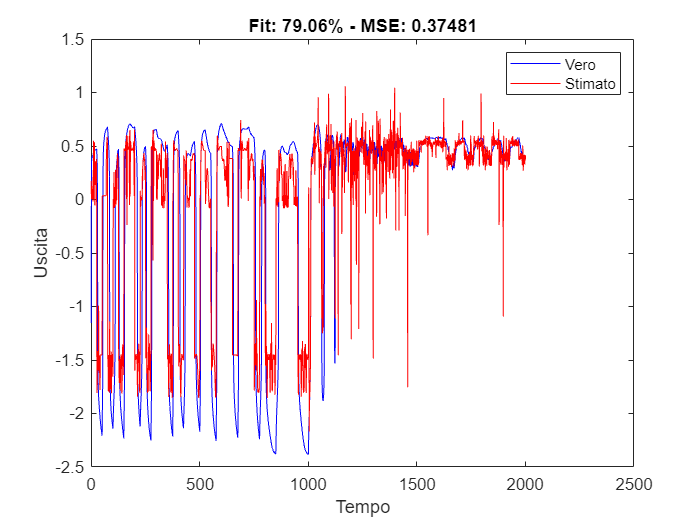

% Calcolo del coefficiente di correlazione
corr = corrcoef(y, (y_sim + noise));
fit_percent = corr(1, 2) * 100;

% Calcolo del Mean Squared Error (MSE)
mse_value = mse(T - (y_sim + noise));


% Visualizzazione dei risultati
figure
plot(T, 'b');
hold on;
plot(y_sim, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato');
title(['Fit: ' num2str(fit_percent, '%.2f') '% - MSE: ' num2str(mse_value)]);


% Visualizzazione del valore percentuale del fit e del MSE
%fprintf('Valore percentuale del fit: %.2f%%\n', fit_percent);
%fprintf('MSE: %.6f\n', mse_value);